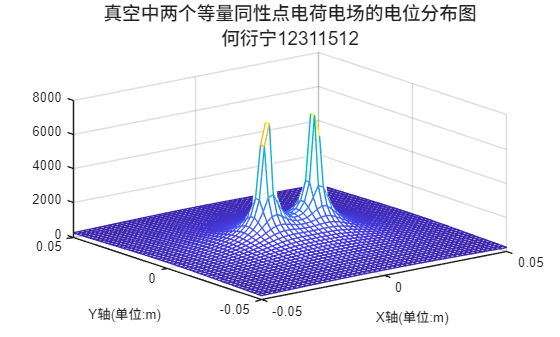

clc,clear,close all;% 清空内存中的所有变量，清空命令窗口中的内容
%两个等量同性点电荷的电场分布
%选择场域范围
k=9e9;%设置静电力衡量
Q=1e-9;% 设置点电荷的电量
Q2=1e-9;
x1=-0.01;%电荷坐标
x2=0.01;
xm=0.05;% 设置场域中x方向的范围
ym=0.05;% 设置场域中y方向的范围
x=linspace(-xm,xm,50);% 将x轴等分成20等份
y=linspace(-ym,ym,50);% 将y轴等分成20等份
[X,Y]=meshgrid(x,y);% 形成场域中各点的坐标
%计算各点电位
R1=sqrt((X-x1).^2+Y.^2);% 计算场域中各点到点电荷的距离
R2=sqrt((X-x2).^2+Y.^2);
V=k*Q./R1+k*Q2./R2;% 计算场域中各点的电位
%绘制各点电位分布
figure;
mesh(X,Y,V);% 绘制出电位的分布图
hold on;
%图表注释
title('真空中两个等量同性点电荷电场的电位分布图','何衍宁12311512','FontSize',14);% 绘出图形标题(注意符号均应为半角英文字符)
xlabel('X轴(单位:m)','FontSize',10);% 绘出X轴标注(注意符号均应为半角英文字符)
ylabel('Y轴(单位:m)','FontSize',10);% 绘出Y轴标注(注意符号均应为半角英文字符)
%保存图片
saveas(gcf,'1.1.jpg');

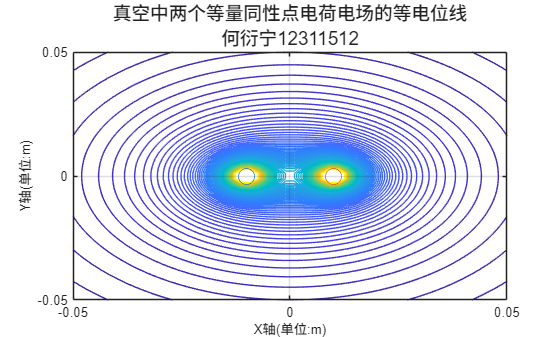

%选择合适的等电位值
Vmin=200;% 设定等位线族的最小电位值
Vmax=4000;% 设定等位线族的最大电位值，拉高最大电位值，更容易观察到高场强区
Veq=linspace(Vmin,Vmax,100);% 设定100条等位线的电位值，提高分辨率，增强连续性
%绘制等电位线分布
figure;
contour(X,Y,V,Veq);% 绘制100条等势线
grid on;% 形成网格
hold on;% 保持图形
%绘制电荷
plot(-0.01,0,'o','MarkerSize',12);
plot(0.01,0,'o','MarkerSize',12);
%图表注释
title('真空中两个等量同性点电荷电场的等电位线','何衍宁12311512','FontSize',14);% 给出图形标题
xlabel('X轴(单位:m)','FontSize',10);% 给出X轴标注
ylabel('Y轴(单位:m)','FontSize',10);% 给出Y轴标注
%保存图片
saveas(gcf,'1.2.jpg');

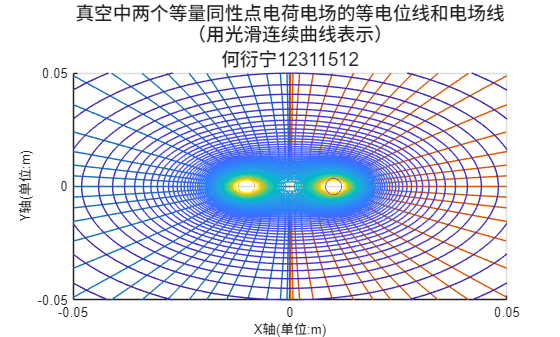

%计算电场线
[Ex,Ey]=gradient(-V); % 计算场域各点的电场强度的两个分量
del_theta=10;% 设置相邻电力线间的角度差
theta=(0:del_theta:360).*pi/180;% 生成电力线的弧度值
xs1=-0.01+0.004*cos(theta);% 生成电力线起点的x轴坐标
xs2=0.01+0.004*cos(theta);
ys1=0.004*sin(theta);% 生成电力线起点的y轴坐标
%绘制场域内的等电位线及电场线（用光滑连续曲线表示）的分布
figure;
streamline(X,Y,Ex,Ey,xs1,ys1);% 生成电力线
streamline(X,Y,Ex,Ey,xs2,ys1);
grid on;% 形成网格
hold on;% 保持图形
contour(X,Y,V,Veq);% 绘制100条等势线
%绘制电荷
plot(-0.01,0,'o','MarkerSize',12);
plot(0.01,0,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中两个等量同性点电荷电场的等电位线和电场线\n（用光滑连续曲线表示）'),'何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'1.3.jpg');

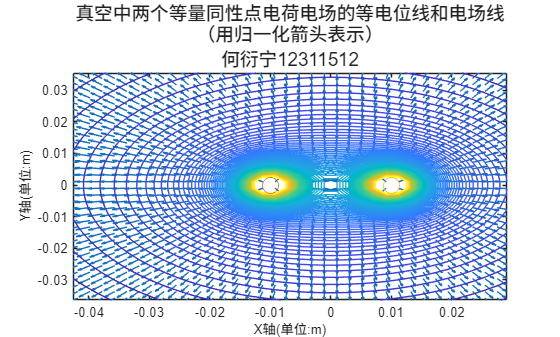

%计算电场强度
E=sqrt(Ex.^2+Ey.^2);% 计算场域各点的电场强度的幅值
Ex=Ex./E;
Ey=Ey./E;% 归一化电场强度值（即使各点场强幅值为1）
%绘制场域内的等电位线及电场线（用归一化箭头表示）的分布
figure;
quiver(X,Y,Ex,Ey);% 用归一化箭头表示场域各点电场强度的方向
hold on;
contour(X,Y,V,Veq);% 绘制等势线
%绘制电荷
plot(-0.01,0,'o','MarkerSize',12);
plot(0.01,0,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中两个等量同性点电荷电场的等电位线和电场线\n（用归一化箭头表示）'),'何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'1.4.jpg');

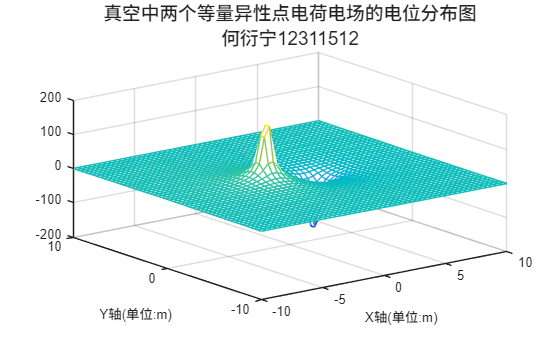

clc,clear,close all;% 清空内存中的所有变量，清空命令窗口中的内容
%两个等量异性点电荷的电场分布
%选择场域范围
k=9e9;
Q=5e-9;
Q2=-5e-9;
xm=10;
ym=10;
x1=-2;
x2=2;
x=linspace(-xm,xm,50);
y=linspace(-ym,ym,50);
[X,Y]=meshgrid(x,y);
%计算各点电位
R1=sqrt((X-x1).^2+Y.^2);
R2=sqrt((X-x2).^2+Y.^2);
V=k*Q./R1+k*Q2./R2;
%绘制各点电位分布
figure;
mesh(X,Y,V);
hold on;
%图表注释
title('真空中两个等量异性点电荷电场的电位分布图','何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'2.1.jpg');

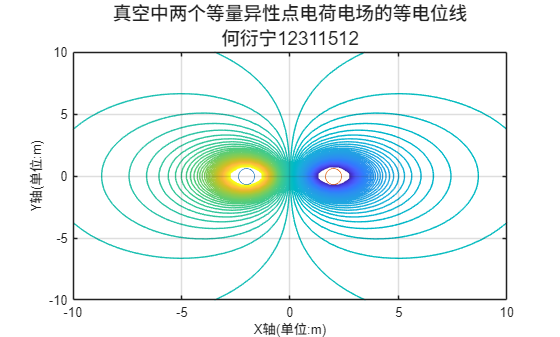

%选择合适的等电位值
Vmin=-50;
Vmax=50;
Veq=linspace(Vmin,Vmax,100);
%绘制等电位线分布
figure;
contour(X,Y,V,Veq);
grid on;
hold on;
%绘制电荷
plot(-2,0,'o','MarkerSize',12);
plot(2,0,'o','MarkerSize',12);
%图表注释
title('真空中两个等量异性点电荷电场的等电位线','何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'2.2.jpg');

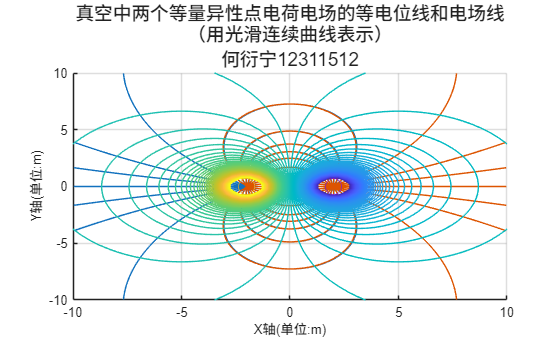

%计算电场线
[Ex,Ey]=gradient(-V);
del_theta=15;
theta=(0:del_theta:360).*pi/180;
xs1=-2+0.004*cos(theta);
xs2=2+0.004*cos(theta);
ys1=0.004*sin(theta);
%绘制场域内的等电位线及电场线（用光滑连续曲线表示）的分布
figure;
streamline(X,Y,Ex,Ey,xs1,ys1);
streamline(X,Y,-Ex,-Ey,xs2,ys1);
grid on;
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-2,0,'o','MarkerSize',12);
plot(2,0,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中两个等量异性点电荷电场的等电位线和电场线\n（用光滑连续曲线表示）'),'何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'2.3.jpg');

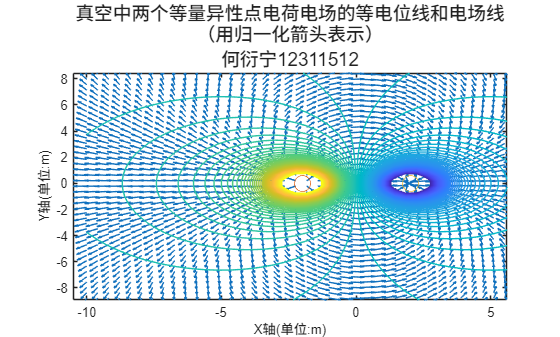

%计算电场强度
E=sqrt(Ex.^2+Ey.^2);
Ex=Ex./E;
Ey=Ey./E;
%绘制场域内的等电位线及电场线（用归一化箭头表示）的分布
figure;
quiver(X,Y,Ex,Ey);
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-2,0,'o','MarkerSize',12);
plot(2,0,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中两个等量异性点电荷电场的等电位线和电场线\n（用归一化箭头表示）'),'何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'2.4.jpg');

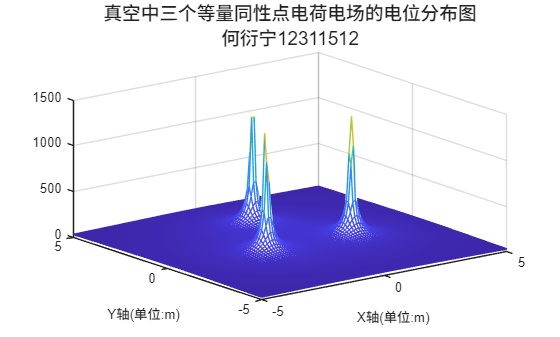

clc,clear,close all;
%位于等边三角形顶点的三个等量同性点电荷的电场分布
%选择场域范围
k=9e9;
Q=8e-9;
xm=5;
ym=5;
x1=-sqrt(3);
x2=sqrt(3);
x=linspace(-xm,xm,100);
y=linspace(-ym,ym,100);
[X,Y]=meshgrid(x,y);
%计算各点电位
R1=sqrt((X-x1).^2+(Y+1).^2);
R2=sqrt((X-x2).^2+(Y+1).^2);
R3=sqrt(X.^2+(Y-2).^2);
V=k*Q./R1+k*Q./R2+k*Q./R3;
%绘制各点电位分布
figure;
mesh(X,Y,V);
hold on;
%图表注释
title('真空中三个等量同性点电荷电场的电位分布图','何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'3.1.jpg');

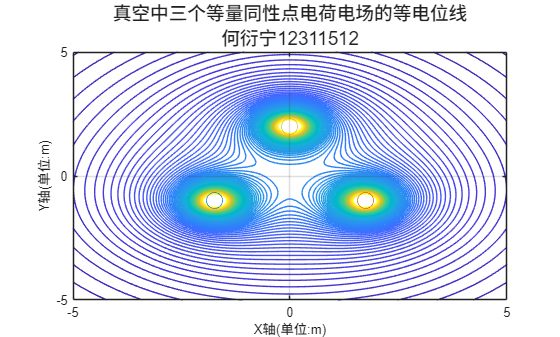

%选择合适的等电位值
Vmin=20;
Vmax=300;
Veq=linspace(Vmin,Vmax,100);
%绘制等电位线分布
figure;
contour(X,Y,V,Veq);
grid on;
hold on;
%绘制电荷
plot(-sqrt(3),-1,'o','MarkerSize',12);
plot(sqrt(3),-1,'o','MarkerSize',12);
plot(0,2,'o','MarkerSize',12);
%图表注释
title('真空中三个等量同性点电荷电场的等电位线','何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'3.2.jpg');

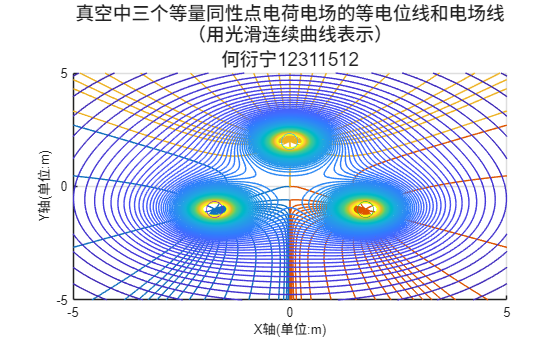

%计算电场线
[Ex,Ey]=gradient(-V);
del_theta=15;
theta=(0:del_theta:360).*pi/180;
xs1=-sqrt(3)+0.004*cos(theta);
xs2=sqrt(3)+0.004*cos(theta);
xs3=0.004*cos(theta);
ys1=-1+0.004*sin(theta);
ys2=-1+0.004*sin(theta);
ys3=2+0.004*sin(theta);
%绘制场域内的等电位线及电场线（用光滑连续曲线表示）的分布
figure;
streamline(X,Y,Ex,Ey,xs1,ys1);
streamline(X,Y,Ex,Ey,xs2,ys2);
streamline(X,Y,Ex,Ey,xs3,ys3);
grid on;
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-sqrt(3),-1,'o','MarkerSize',12);
plot(sqrt(3),-1,'o','MarkerSize',12);
plot(0,2,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中三个等量同性点电荷电场的等电位线和电场线\n（用光滑连续曲线表示）'),'何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'3.3.jpg');

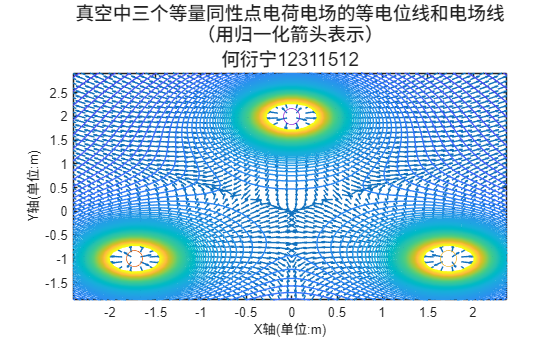

%计算电场强度
E=sqrt(Ex.^2+Ey.^2);
Ex=Ex./E;
Ey=Ey./E;
%绘制场域内的等电位线及电场线（用归一化箭头表示）的分布
figure;
quiver(X,Y,Ex,Ey);
hold on;
contour(X,Y,V,Veq);
%绘制电荷
plot(-sqrt(3),-1,'o','MarkerSize',12);
plot(sqrt(3),-1,'o','MarkerSize',12);
plot(0,2,'o','MarkerSize',12);
%图表注释
title(sprintf('真空中三个等量同性点电荷电场的等电位线和电场线\n（用归一化箭头表示）'),'何衍宁12311512','FontSize',14);
xlabel('X轴(单位:m)','FontSize',10);
ylabel('Y轴(单位:m)','FontSize',10);
%保存图片
saveas(gcf,'3.4.jpg');